依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

热图A：naive aud-water, leant aud-water;

DataSet=TransferLearning.FullCalcium;

排序热图2

LAFinal=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'Fig2B'),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median));

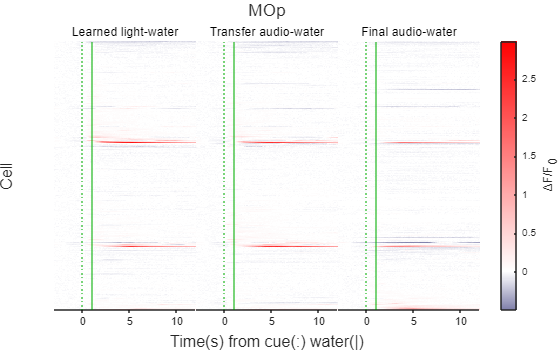

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Data=LAFinal.NTATS{:,:,["Learned_light_water","Transfer_audio_water","Final_audio_water"]};
%Data=Data(any(Data,2:3),:,:);
Layout=TransferLearning.AucGroupSortedHeatmap(Data,["Learned light-water","Transfer audio-water","Final audio-water"],Colors,false);
title(Layout,'MOp');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('Fig2B.svg'),'-dsvg');